# Longitudinal Vehicle - Simulation Case

## Coastdown

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
Vehicle1D_harness_setup
Vehicle1D_setSimCase_Constant

Setting up simulation...
Simulation case: Constant inputs
Setting simulation stop time to 1000 sec.
Setting block parameters...
Setting initial conditions...
initial.loadInertiaSpd_rpm = 0
initial.vehicle_speed_kph = 0


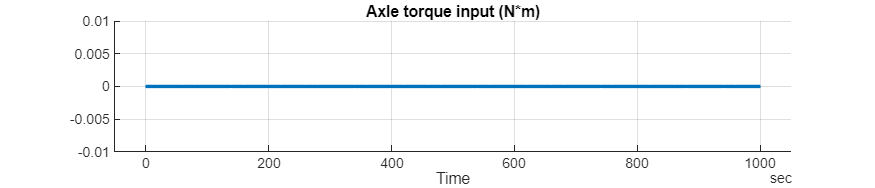

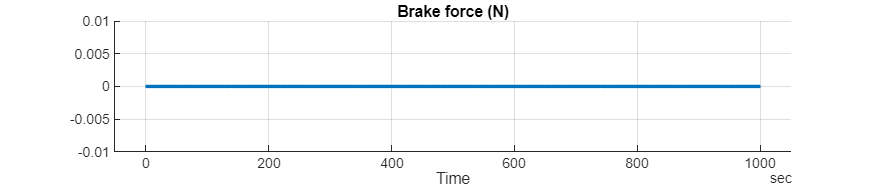

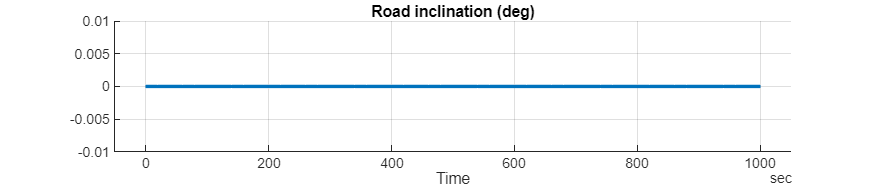

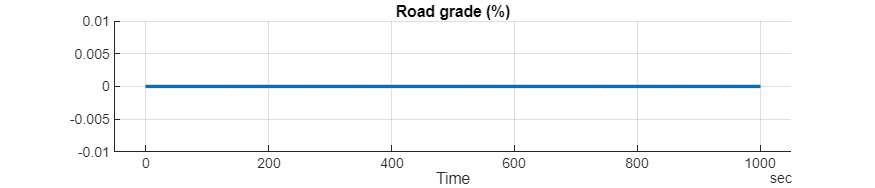

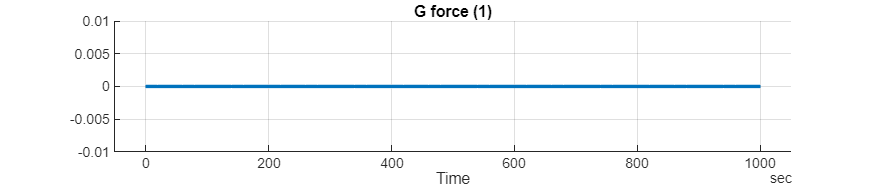

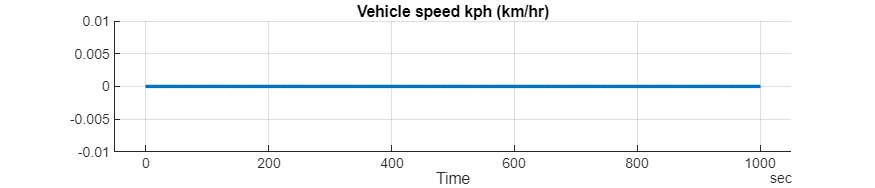

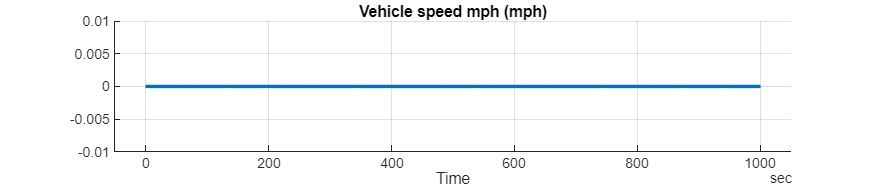

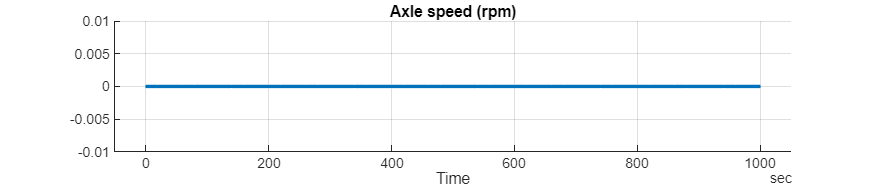

simOut = sim(mdl);
simData = extractTimetable(simOut.logsout);
Vehicle1D_plotResults( SimData = simData, FigureHeight = 150 );

* Copyright 2020-2025 The Mathworks, Inc.*